clear all;

k1 = 3.26;
a01 = 1;
T1 = 9.5;
xi = 0.36;
k2 = 1;
a02 = 1;
T2 = 0;
T = 1;

a0 = (a01*a02) / (T1^2);
a1 = (2*xi) / T1;

b0 = k1*k2/(T1^2);

Ac = [0, 1; -a0, -a1];
Bc = [0; 1];
C = [b0, 0];

A = 0;
k = 100;
for i = 0:k
    A = A + (Ac^i * T^i) / factorial(i);
end
B = 0;
for i = 1:k
    B = B + ((Ac^(i - 1) * T^i) / factorial(i));
end

A

A =     0.9946    0.9613
   -0.0107    0.9217


B = B * Bc;
eig_A = eig(A);
norm(eig_A(1));

U = [B, A*B];
rank(U);

V = [C; C*A];
rank(V);

G = [0, 1; 0, 0];
H = [1, 0];
V = [H; H*G];
rank(V);

P = sylvester(A, -G, B*H)

P =    -0.5124   -1.5848
    1.0370    1.1067


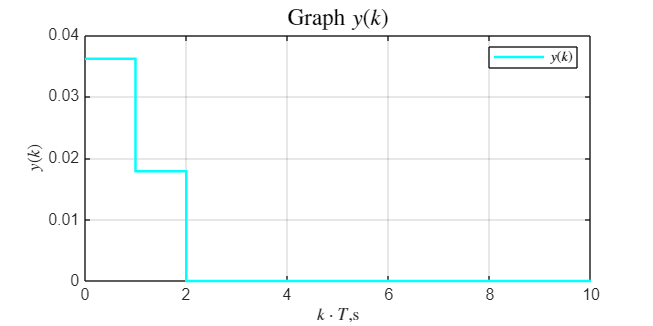

K = H * pinv(P);
%K = [0, 0]
d = det(P);
new_1 = A - B * K;
e = eig(new_1);

%====================================

set_param('task_1_schem/x', 'VariableName', 'x');
set_param('task_1_schem/y', 'VariableName', 'y');

out = sim('task_1_schem');
x_data = out.x.Data;
t_time = out.x.Time;
y_data = out.y.Data;


% Построение графика

% Определяем цвета для линий
a_color = '#00FFFF'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);
stairs(t_time, y_data, '-', 'LineWidth', 1.5, 'Color', a_color);

grid on;

title('Graph $y(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k \cdot T$,s', 'Interpreter', 'latex');
legend('$y(k)$','Interpreter', 'latex')
hold off;

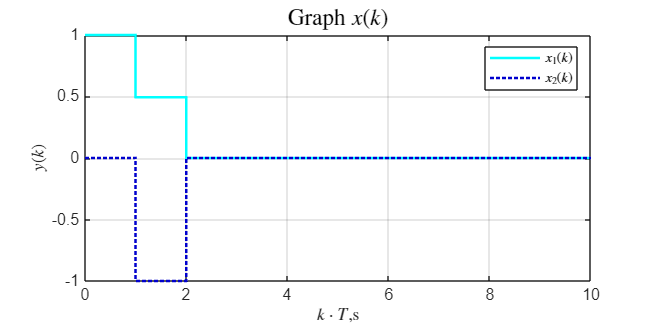


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '1_y.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);

stairs(t_time, x_data(:,1), '-', 'LineWidth', 1.5, 'Color', a_color); 
hold on;
stairs(t_time, x_data(:,2), ':', 'LineWidth', 1.5, 'Color', d_color);

grid on;

title('Graph $x(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k\cdot T$,s', 'Interpreter', 'latex');
legend('$x_1(k)$', '$x_2(k)$','Interpreter', 'latex')
hold off;


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '1_x.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);
